# Tests for debugging purposes

## Nonconvex problem

## 
$$\min_{X\in\mathbb{R}^{n\times p},\, Q\in Stf(r,n)}  \sum_j \|X-Y_jQ_j\|^2 
\\
=: \min f
\\
\nabla f(X,Q) = 2\bigg(\sum_j(X-Y_jQ_j), Y^\top(YQ-X)\bigg)
\\
\nabla^2 f(X,Q)[U,V] = \nabla f(U,V)$$


### Gradient

The slope should be 2. It appears to be: 2.00001.
If it is far from 2, then directional derivatives might be erroneous.


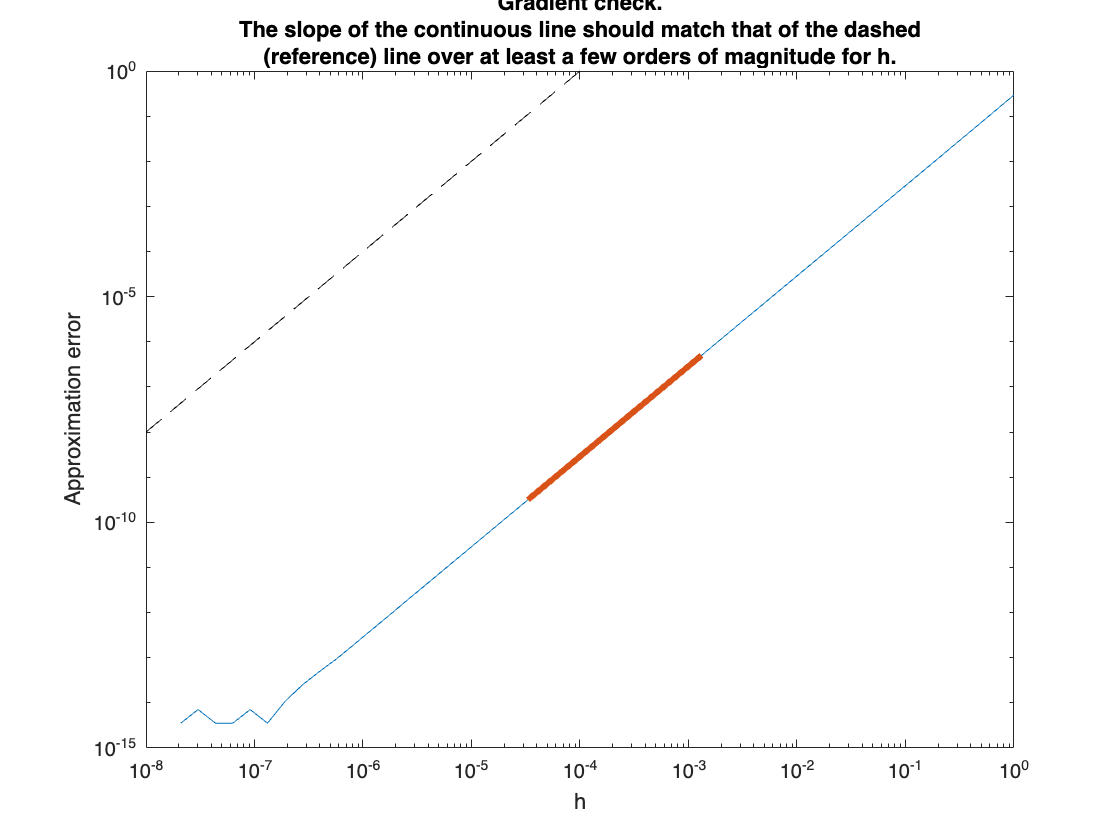

The residual should be 0, or very close. Residual: 1.51208e-15.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


clear
n=5; % data dimension
k=5; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+1; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

checkgradient(prob);

### Hessian

checkhessian(prob);

The slope should be 3. It appears to be: 3.00036.
If it is far from 3, then directional derivatives,
the gradient or the Hessian might be erroneous.
Tangency residual should be zero, or very close; residual: 3.04147e-16.
If it is far from 0, then the Hessian is not in the tangent space.
||a*H[d1] + b*H[d2] - H[a*d1+b*d2]|| should be zero, or very close.
	Value: 4.53142e-16 (norm of H[a*d1+b*d2]: 1.66209)
If it is far from 0, then the Hessian is not linear.
<d1, H[d2]> - <H[d1], d2> should be zero, or very close.
	Value: 0.0930706 - 0.0930706 = 6.93889e-17.
If it is far from 0, then the Hessian is not symmetric.


### Optimization

clear
n=32; % data dimension
k=10; % number of matrices
r=round(n/2); % size of factorization Y of data A
p=r+5; % size of factorization X of barycenter B (r<=p)
A = data(n,k,r);
prob = nonconvex_problem(A,r,p);

options.debug=0;
%options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob,[],options);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +1.1741059303963859e+03   7.321077e+01
acc TR+       1   +9.3360429329473743e+02   6.173398e+01           1           1           1   exceeded trust region
acc TR+       2   +5.9370382605998736e+02   3.804584e+01           1           1           1   exceeded trust region
acc TR+       3   +3.5476498809330803e+02   1.343351e+01           2           2           2   negative curvature
REJ TR-       4   +3.5476498809330803e+02   1.343351e+01           2           2           2   exceeded trust region
acc TR+       5   +3.1429096340154911e+02   1.471360e+01           1           0           2   exceeded trust region
REJ TR-       6   +3.1429096340154911e+02   1.471360e+01           3           3           2   exceeded trust region
acc TR+       7   +2.8896724432634579e+02   9.330497e+00           1           0           2   exceeded trust region
acc           8   +2.

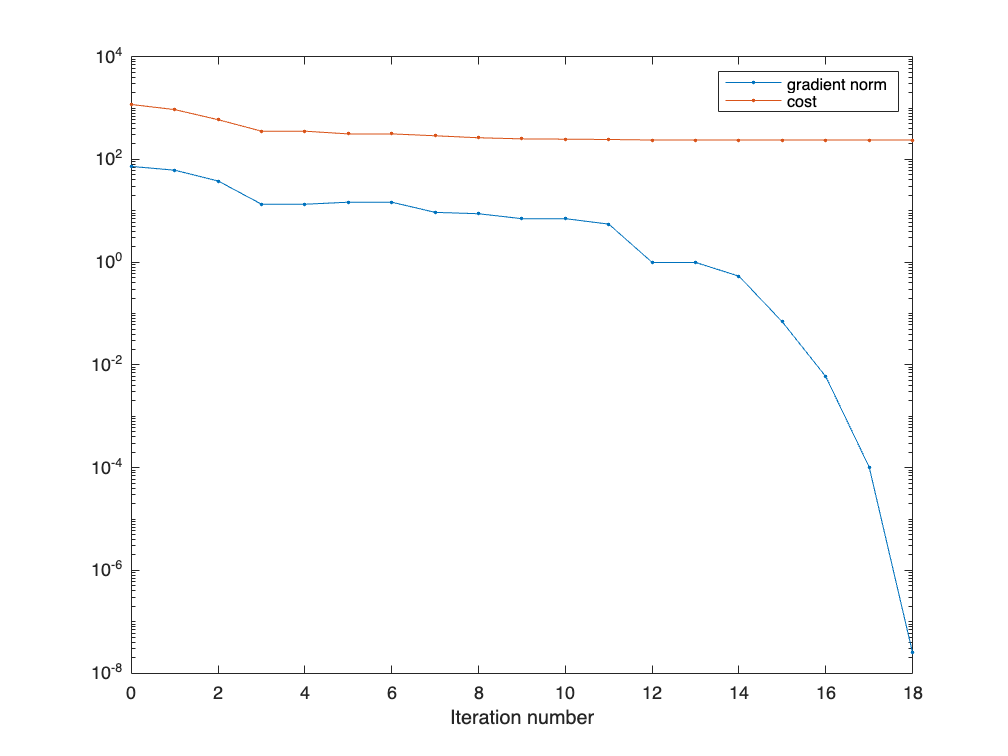

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');
legend("gradient norm","cost")

## Convex problem

## 
$$\min_{B\geq0} \sum_j tr\big(A_j+B - 2(A_j^{1/2}BA_j^{1/2})^{1/2}\big)
\\
=: \min Var
\\
\nabla Var(B) =  kI_k - \sum_j B^{-1/2}(B^{1/2}A_jB^{1/2})B^{-1/2}}$$


### Gradient

The slope should be 2. It appears to be: 2.00411.
If it is far from 2, then directional derivatives might be erroneous.


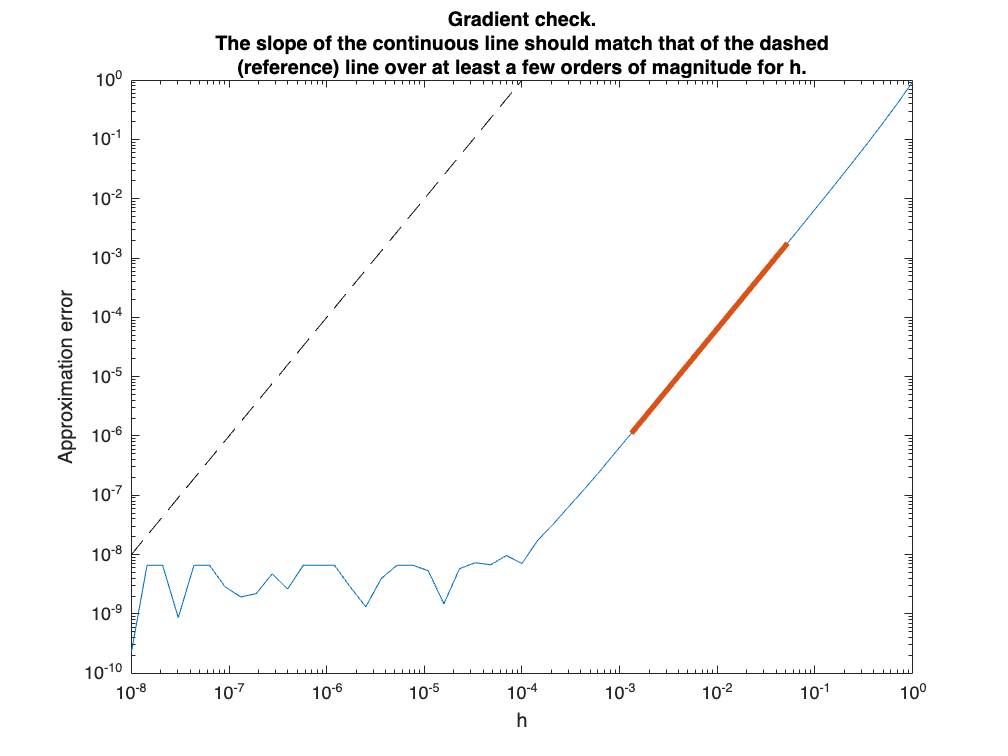

The residual should be 0, or very close. Residual: 1.18678e-18.
If it is far from 0, then the gradient is not in the tangent space.
In certain cases (e.g., hyperbolicfactory), the tangency test is inconclusive.


clear
n=2; % data dimension
k=4; % number of matrices
A = data(n,k,n-1);
prob2 = convex_problem(A);

checkgradient(prob2);

### Manopt optimization

clear
n=4; % data matrix dimension
k=10; % number of data samples
r=n; % rank of data
A = data(n,k,r);
prob2 = convex_problem(A);

% options.debug=1;
% options.statsfun = @variance_statsfun;
[x, xcost, info, options] = trustregions(prob2);

           iter                  cost val     grad. norm    numinner     hessvec   numstored   stopreason
              0   +5.2254578025372904e+00   1.281396e+00
acc TR+       1   +4.7505123813203198e+00   1.129032e+00           1           1           1   negative curvature
acc           2   +4.1019236145388884e+00   4.804036e-01           1           1           1   negative curvature
acc TR-       3   +4.0766665688186325e+00   5.156212e-01           2           2           2   reached target residual-kappa (linear)
acc           4   +4.0172105389448580e+00   1.303667e-01           2           2           2   reached target residual-kappa (linear)
acc           5   +4.0122638014327539e+00   1.437888e-02           2           2           2   reached target residual-kappa (linear)
acc           6   +4.0121986280508111e+00   2.705932e-04           3           3           2   reached target residual-theta (superlinear)
acc           7   +4.0121985989932849e+00   9.761354e-08           7

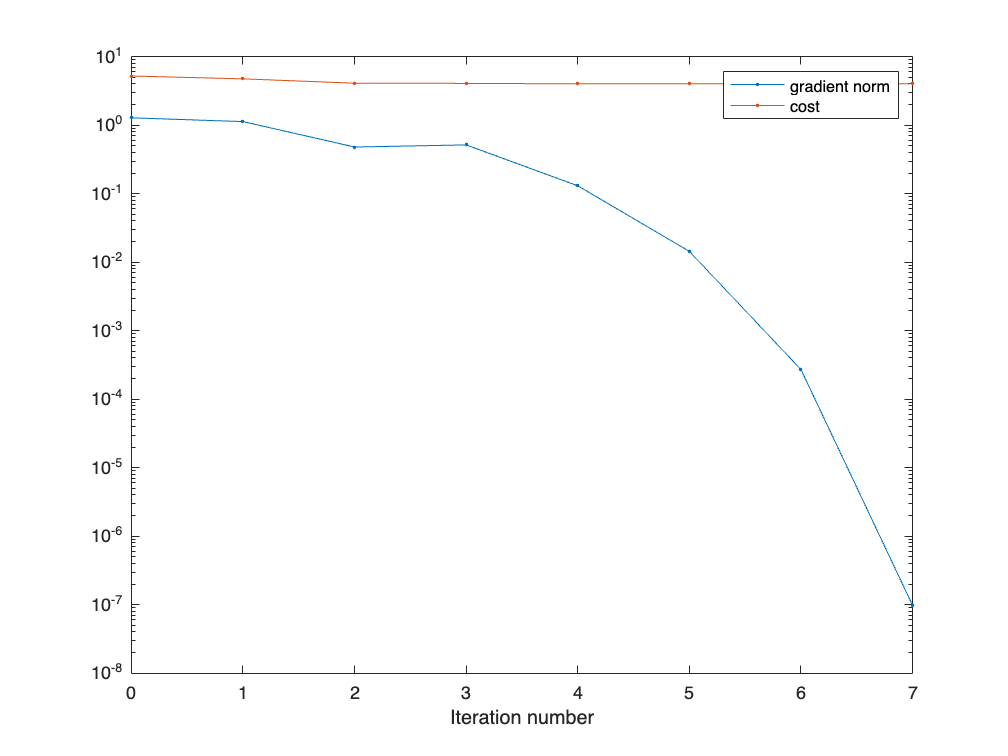

figure;
semilogy([info.iter], [info.gradnorm], '.-',[info.iter],[info.cost],'.-');
xlabel('Iteration number');
legend("gradient norm","cost")

### CVX optimization

clear
n=2; % data dimension
k=1000; % number of matrices
r=n;
A = data(n,k,r);
[B,Bcost,info] = cvx_solve(A)

B =     1.3342    0.0976
    0.0976    1.2974


Bcost = 1.3710

info = struct with fields:
      cost: 1.3710
    status: 'Solved'
      iter: 13
       tol: 2.5116e-09
    optbnd: 1.3710
      time: 38.2700


fprintf("%e\n",eig(B))

1.216471e+00
1.415151e+00


fprintf("%e\n",eig(A(:,:,1)))

2.458212e+00
4.100170e+00


### Fast vs slow version

clear
Nreapeat = 5;
nn=2; % data dimension
kk=round(linspace(1,50,5)); % number of matrices
for jn=1:length(nn)
    n=nn(jn);
    r=n;
    for jk=1:length(kk)
        k=kk(jk);
        A = data(n,k,r);
        for rep=1:Nreapeat
            [B,Bcost,info] = cvx_solve(A,"fast");
            time.fast(jn,jk,rep)=info.time;
            [B_slow,Bcost_slow,info_slow] = cvx_solve(A,"slow");
            time.slow(jn,jk,rep)=info_slow.time;
            Berr(jn,jk,rep) = norm(B-B_slow,"fro") / norm(B_slow,"fro");
        end
    end
end

max(Berr,[],"all")

ans = 2.8590e-05

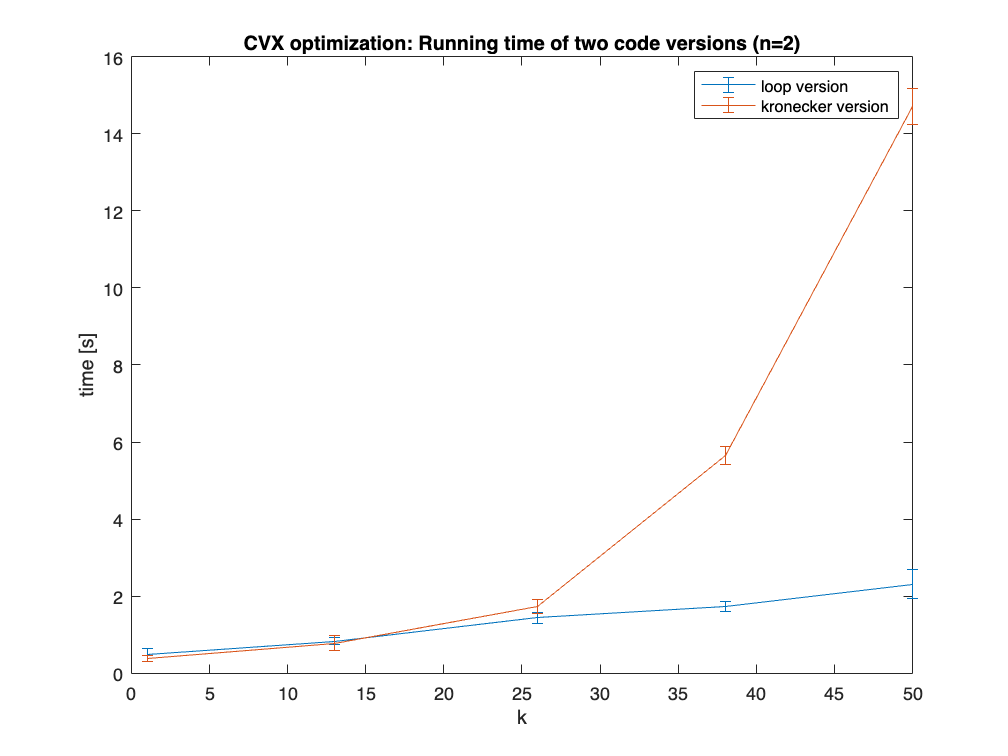

[sigma.slow,mu.slow] = std(time.slow,0,3);
[sigma.fast,mu.fast] = std(time.fast,0,3);
errorbar(kk,mu.fast,sigma.fast)
hold on
errorbar(kk,mu.slow,sigma.slow)
legend("loop version","kronecker version")
xlabel("k")
ylabel("time [s]")
title(sprintf("CVX optimization: Running time of two code versions (n=%d)",n))
hold off

### Convex Manopt VS CVX

clear
Nrepeat=10

Nrepeat = 10

relat_err=zeros(10,1);
for rep=1:Nrepeat
    n=randi([1,10]); % data dimension
    k=randi([1,10]); % number of matrices
    r=randi([1,n]);
    A = data(n,k,r);
    prob = convex_problem(A);
    options.verbosity = 0;
    options.maxtime=10;
    [B_cvx,Bcost_cvx,info_cvx] = cvx_solve(A);
    [B, Bcost, info, options] = trustregions(prob,[],options);
    B_relative_error(rep) = norm(B-B_cvx,"fro")/norm(B_cvx,"fro");
end

mean_err = mean(relat_err);
std_err = std(relat_err);
max_err = max(relat_err);
fprintf("relative error = %e +- %e \n maximum error = %e",mean_err,std_err,max_err)

relative error = 0.000000e+00 +- 0.000000e+00 
 maximum error = 0.000000e+00

Bcost

Bcost = 3.4410

info(end)

ans = struct with fields:
            iter: 630
            cost: 3.4410
        gradnorm: 4.0793e-06
           Delta: 1.7347e-18
            time: 10.0165
             rho: 1.0000
          rhonum: 7.6405e-13
          rhoden: 7.6405e-13
        accepted: 1
        stepsize: 8.6736e-19
     limitedbyTR: 1
        numinner: 1
    hessvecevals: 1
    memorytCG_MB: 0.0027
          hooked: 0


info_cvx

info_cvx = struct with fields:
      cost: 3.4410
    status: 'Inaccurate/Solved'
      iter: 34
       tol: 5.8052e-08
    optbnd: 3.4410
      time: 9.5800


## Statistics

### Convergence of barycenter

clear
n=2; % data dimension
kk=round(linspace(1,100,5)); % number of matrices
k_big=1000;
r=n;

Btrue = cvx_solve(data(n,k_big,r));
for jk=1:length(kk)
    A = data(n,kk(jk),r);
    [B(:,:,jk),Bcost(jk),info(jk)] = cvx_solve(A);
end

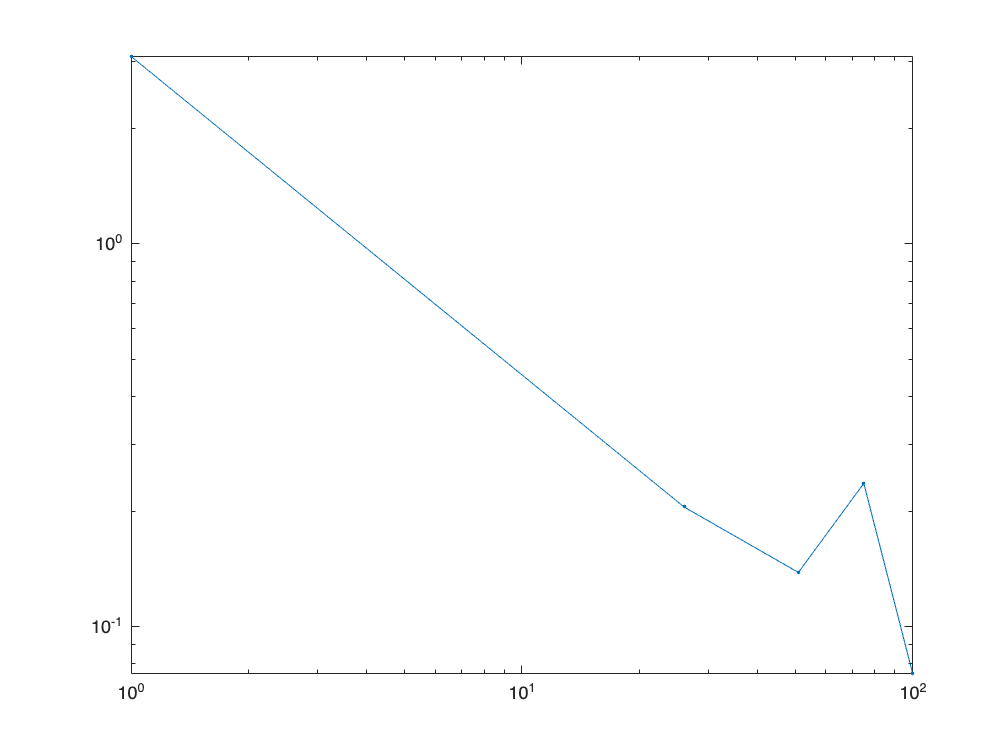

Berr = squeeze(pagenorm(Btrue-B,"fro"));
loglog(kk,Berr/norm(Btrue,"fro"),".-");

### Theoretical barycenter

clear
n=5; % data dimension
k=10; % number of matrices
r=n-1;
B=10*data(n,1,r)

B =    50.0250   -2.1758   26.9740  -38.4824    0.9908
   -2.1758   15.2116  -14.3974   21.5906   -3.7100
   26.9740  -14.3974   52.3804  -29.4223    1.9873
  -38.4824   21.5906  -29.4223   64.9648   -1.9532
    0.9908   -3.7100    1.9873   -1.9532    3.9026


A = data_scaled(B,k);
A2 = data_scaled(B,k,"exact");
prob = convex_problem(A);
prob2 = convex_problem(A2);
norm(getGradient(prob,B),"fro")

ans = 8.7656e+12

norm(getGradient(prob2,B),"fro")

ans = 3.9110e+12

norm(getGradient(prob,prob.M.rand()),"fro")

ans = 18.5036

### Convergence to theoretical barycenter

clear
n=2; % data dimension
kk=round(logspace(0,3,10)); % number of matrices
r=n;
Btrue=data(n,1,r);
A = data_scaled(Btrue,kk(end));
for jk=1:length(kk)
    k=kk(jk);
    [B(:,:,jk),Bcost(jk),info(jk)] = cvx_solve(A(:,:,1:k));
    Btruecost(jk) = cost_variance(A,Btrue);
end

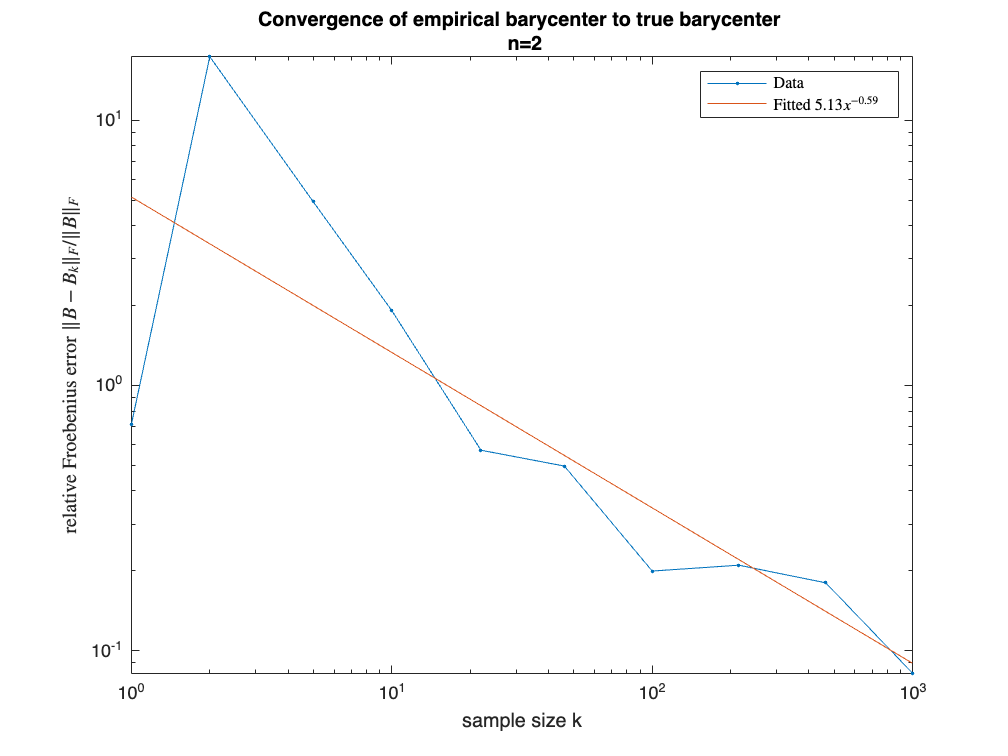

Berr = squeeze(pagenorm(Btrue-B,"fro"));
Berr_relat = Berr/norm(Btrue,"fro");
loglog(kk,Berr_relat,".-")
poly=polyfit(log(kk),log(Berr_relat),1);
hold on
loglog(kk,exp(polyval(poly,log(kk))))
legend("Data",sprintf("Fitted $%.2fx^{%.2f}$",exp(poly(2)),poly(1)),'Interpreter','latex')
title(sprintf("Convergence of empirical barycenter to true barycenter \n n=%d",n))
xlabel("Sample size k")
ylabel("Relative Froebenius error $\| B-B_k\| _F/\| B\| _F$",Interpreter="latex")

hold off
plot(kk,Bcost,kk,Btruecost)
legend("Empirical barycenter","True barycenter")
title("Convergence of cost")
xlabel("Sample size k")
ylabel("Cost (B-W variance)")

## Data generation

clear
n=5;
k=10;
r=2;
for rep = 1:10
    Btrue=data(n,1,r);
    A=data_scaled(Btrue,k,"exact");
    [B,Bcost,info] = cvx_solve(A);
    err_relat(rep) = norm(Btrue-B,"fro")/norm(Btrue,"fro");
end
max(err_relat)

ans = 1.4060e-04

## Relaxed problem

## 
$$\min_{S\in Sym(rk)_{\geq0} ,\  S_{jj}=I_r} <-Y^\top Y,S>
\\
where \ Y=[Y_1,\dots,Y_k]$$



clear
n=5;
k=5;
rr=1:n;
i=0;
for r=rr
    i=i+1
    Btrue=data(n,1,r);
    A=data_scaled(Btrue,k,"exact");
    Bconvex=cvx_solve(A);
    err_convex(i) = norm(Btrue-Bconvex,"fro");
    [B,Bcost,info] = cvx_solve_relaxed(A,r);
    err(i) = norm(Btrue-B,"fro")/norm(Btrue,"fro");
end

i = 1

i = 2

i = 3

i = 4

i = 5

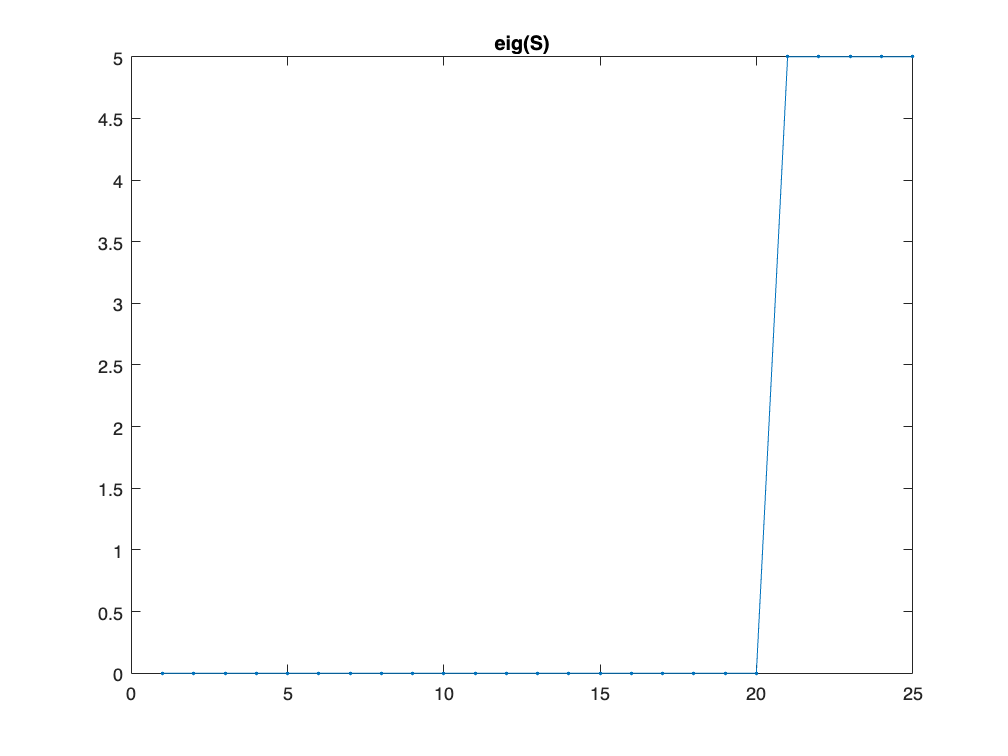

plot(eig(info.S),'.-')
title("eig(S)")

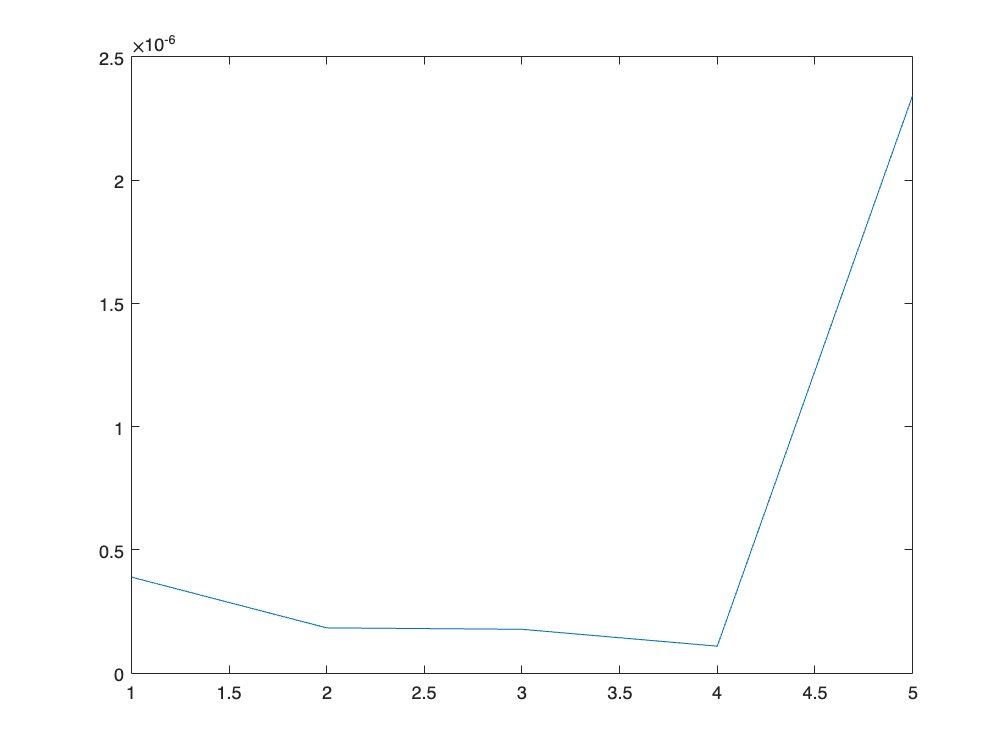

plot(err_convex)

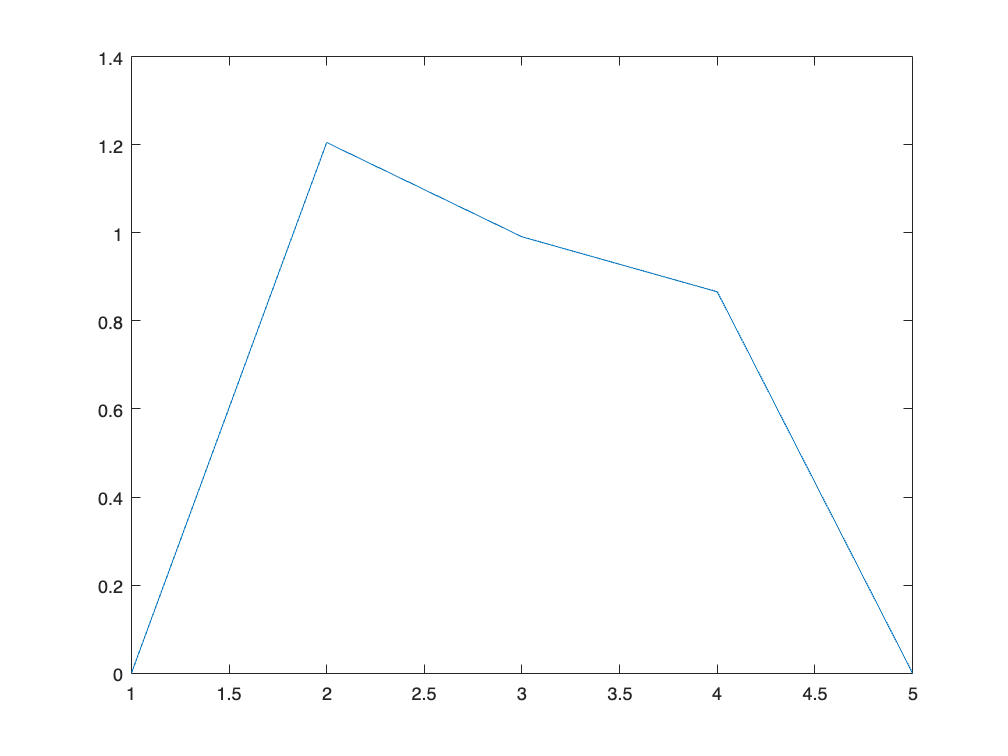

plot(err)

### Ranks of S possible

clear
r=5;
p=r+2;
k=3;
ss=r:min([p,r*k]);
for s=ss
    [S,Q2,Q3] = build_SQ(r,p,k,s);
end
Q3

Q3 = Q3(:,:,1) =

     1     0     0     0     0     0     0
     0     1     0     0     0     0     0
     0     0     1     0     0     0     0
     0     0     0     1     0     0     0
     0     0     0     0     1     0     0


Q3(:,:,2) =

     0     0     0     0     0     1     0
     0     0     0     0     0     0     1
     0     0     1     0     0     0     0
     0     0     0     1     0     0     0
     0     0     0     0     1     0     0


Q3(:,:,3) =

     1     0     0     0     0     0     0
     0     1     0     0     0     0     0
     0     0     1     0     0     0     0
     0     0     0     1     0     0     0
     0     0     0     0     1     0     0
